# **Лабораторная работа №3**

## **Настройка регуляторов по звеньям**

**Студент: Топольницкий А.**

**Группа: R4134c**

**Поток: МИУР 1.1**

**Вариант: 2 **

**Робот: ABB IRB140**

**Задание:**

- Загрузить модель робота в соответствии с вариантом;

- Настроить генератор траектории в среде Simulink, опираясь на результаты ЛР №2. Метод построения траектории выбрать на своё усмотрение. Начальное и конечное положение схвата манипулятора должны лежать в пределах рабочей зоны. Провести проверку выбранных точек, решим обратную задача кинематики;

- Загрузить Simulink файл с контуром управления по скорости "vloop_test";

- В соответсвтии с вариантом подобрать или взять из паспорта манипулятора необходимые параметры двигателей для каждого звена. Рассчитать инерцию каждого звена;

- Используя генератор сигнала, подобрать необходимые коэффициенты пропорциональной и интегральной части регулятора;

- Загрузить Simulink файл с контуром управления по положению "ploop_test";

- Заменить исходный блок "vloop" на настроенный ранее. Установить значение передаточного числа двигателя согласно параметрам двигателя;

- Для каждого звена провести настройку, подобрав необходимый коэффициент Kp;

- Отладить и оценить качество работы алгоритма управления манипулятором для различных недетерминированных эффектов - шумы, появление полезной нагрузки на энд-эффекторе;

- Определить показатели качества управления (время переходного процесса, максимальную и установившуюся ошибки);

- Определить отношение максимального и минимальнго элементов матрицы масс при движении вдоль заданной траектории.

### **Ход работы**

**Пункт 1. Загрузить модель робота в соответствии с вариантом**

mdl_irb140

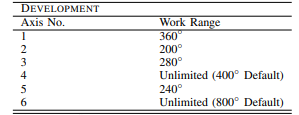

Рис. 1. Данные по ограничениям по звенья

lims = deg2rad([-180 180 ; -100 100; -140 140; -200 200; -120 120; -400 400]);  % переводим градусы в радианы для каждого звена
% задаём ограничения для каждого из звеньев
for i = 1:6
    irb140.qlim(i,1) = lims(i,1);
    irb140.qlim(i,2) = lims(i,2);
end

Рис. 2. Данные по массам звеньев и массе базы

m = [35 25 18 6.5 1.5 1.5];
% зададим массы звеньев и их габариты
for i = 1:6
    irb140.links(1,i).m = m(i);
end
w = [0.08 0.06 0.06 0.04 0.04 0.02];

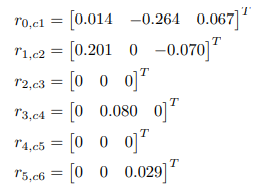

Рис.3. Данные для центров масс

% задаём координаты центром масс каждого звена
irb140.links(1,1).r = [0.014 -0.264 0.067];
irb140.links(1,2).r = [0.201 0 -0.07];
irb140.links(1,3).r = [0 0 0];
irb140.links(1,4).r = [0 0.080 0];
irb140.links(1,5).r = [0 0 0];
irb140.links(1,6).r = [0 0 0.029];

% производим расчёт инерции для каждого звена
for i=1:6
    irb140.links(1,i).I = zeros(3,3);
end

for i=1:6
    if i == 1
        irb140.links(1,i).I(1,1) = 1/12 * m(i) * (w(i)^2 + irb140.links(1,i).a^2);
        irb140.links(1,i).I(2,2) = 1/12 * m(i) * 2 * w(i)^2;
        irb140.links(1,i).I(3,3) = 1/12 * m(i) * 2 * w(i)^2;
    else
        irb140.links(1,i).I(1,1) = m(i) * (w(i) / 2)^ 2;
        irb140.links(1,i).I(2,2) = 1/12 * m(i) * (3 * (w(i)/2)^2 + irb140.links(1,i).a^2);
        irb140.links(1,i).I(3,3) = 1/12 * m(i) * (3 * (w(i)/2)^2 + irb140.links(1,i).a^2);
    end
end

К сожалению, никакой информации по поводу параметров двигателей найти не удалось, хотя поиски шли в течение нескольких часов. Поэтому возьмём параметры для двигателей с робота Пума_560.

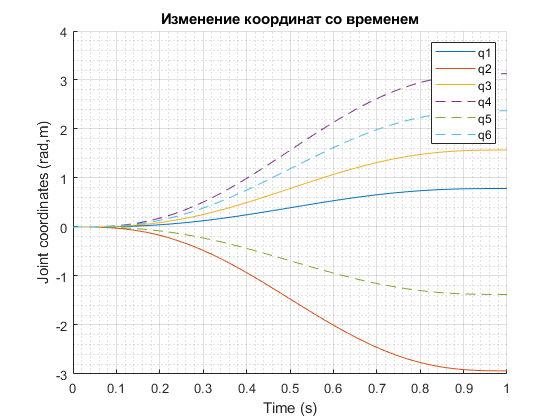

mdl_puma560
for i = 1:6
    irb140.links(1,i).Jm =p560.links(1,i).Jm;
    irb140.links(1,i).B = p560.links(1,i).B;
    irb140.links(1,i).G = p560.links(1,i).G;
end
% Задание конечной точки
dot = [-0.5, -0.5, 0.5];
% Задание количества шагов
n = 1000;
% Задание времени
t_end = 1;
t = linspace(0, t_end, n)'; % задаём время пути

q_end=irb140.ikine6s(transl(dot) * trotx(pi/2) * troty(pi/3) * trotz(pi/4)); % transl - линейная составляющаяя однородной матрицы, trotx - вращательная
% составляющая вокруг оси х, y, z

[q, q_d, q_dd] = jtraj(qz, q_end, t); % рассчитаем траекторию и построим изменение координат со временем
figure
qplot(t, q);
title ('Изменение координат со временем')
grid minor

**Пункт 3. Загрузить Simulink файл с контуром управления по скорости "vloop_test"**

Поскольку мы управляем звеньями по отдельности и каждое последующее звено влияет на предыдущее, то необходимо это как-то учесть.

Можно сделать это так, как реализовано в пособии по нашему Toolbox.

% Расчет матриц инерций по траектории
M = zeros(6, n); % зададим пустую матрицу
for i = 1 : size(q,1)
    M_full = irb140.inertia(q(i,:)); % для каждого звена вычисляем
    % матрицу инерции в зависимости от координат при движении по траектории
    M(1,i) = M_full(1,1);
    M(2,i) = M_full(2,2);
    M(3,i) = M_full(3,3);
    M(4,i) = M_full(4,4);
    M(5,i) = M_full(5,5);
    M(6,i) = M_full(6,6);
end
% вычислим среднее значение по траектории
M_mean = zeros(1, 6);
for i = 1 : 6
    M_mean(i) = mean(M(i,:), 'all');
end

% найдём отношение максимального к минимальному моментов инерции на
% траектории
ratio = zeros(1, 6);
for i = 1 : 6
    ratio(i) = max(M(i,:),[],'all') / min(M(i,:),[],'all');
end
ratio

ratio =     9.3537    1.1476    1.0260    1.0295    1.0078    1.0000


, где Im - инерция двигателя, G - передаточное число двигателя, М22 - как раз наше среднее значение из матрицы инерции

% Расчет инерции звена
for i = 1 : 6
    J(i) = irb140.links(1, i).Jm + M_mean(i) / irb140.links(1, i).G^2;
end

**Пункт 4 и 5. Задаём параметры и подбираем коэффициенты для регуляторов**

motor_const = [0.23, 0.15, 0.15, 0.089, 0.034, 0.032];
tau_m = [15, 10, 7, 4, 3, 3];

% Коэффициенты регуляторов
% контур управления по скорости "vloop"
Kv = [10, 1.5, 1.5, 0.5, 0.5, 0.5];
Ki = [5, 1, 1, 1, 1, 1];
% контур управления по положению "ploop"
Kpl = [4000 4000 5000 5000 5000 5000];

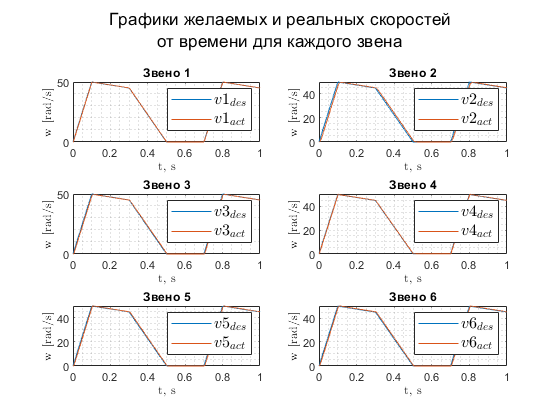

simout_vloop = sim('Lab3_Topolnitskii_velocity.slx');
% графики по скорости для каждого звена
figure;

subplot(3,2,1)
plot(simout_vloop.vloop.time', simout_vloop.vloop.signals.values(:,1))
hold on
plot(simout_vloop.vloop.time', simout_vloop.vloop.signals.values(:,2), 'LineStyle',"-")
title('Звено 1')
grid minor
legend('$v1_{des}$', '$v1_{act}$', 'fontsize',12,'interpreter','latex');
xlabel('t, s','Interpreter',"latex")
ylabel('w [rad/s]','Interpreter',"latex")

subplot(3,2,2)
plot(simout_vloop.vloop.time', simout_vloop.vloop.signals.values(:,6))
hold on
plot(simout_vloop.vloop.time', simout_vloop.vloop.signals.values(:,7), 'LineStyle',"-")
title('Звено 2')
grid minor
legend('$v2_{des}$', '$v2_{act}$', 'fontsize',12,'interpreter','latex');
xlabel('t, s','Interpreter',"latex")
ylabel('w [rad/s]','Interpreter',"latex")

subplot(3,2,3)
plot(simout_vloop.vloop.time', simout_vloop.vloop.signals.values(:,11))
hold on
plot(simout_vloop.vloop.time', simout_vloop.vloop.signals.values(:,12), 'LineStyle',"-")
title('Звено 3')
grid minor
legend('$v3_{des}$', '$v3_{act}$', 'fontsize',12,'interpreter','latex');
xlabel('t, s','Interpreter',"latex")
ylabel('w [rad/s]','Interpreter',"latex")

subplot(3,2,4)
plot(simout_vloop.vloop.time', simout_vloop.vloop.signals.values(:,16))
hold on
plot(simout_vloop.vloop.time', simout_vloop.vloop.signals.values(:,17), 'LineStyle',"-")
title('Звено 4')
grid minor
legend('$v4_{des}$', '$v4_{act}$', 'fontsize',12,'interpreter','latex');
xlabel('t, s','Interpreter',"latex")
ylabel('w [rad/s]','Interpreter',"latex")

subplot(3,2,5)
plot(simout_vloop.vloop.time', simout_vloop.vloop.signals.values(:,21))
hold on
plot(simout_vloop.vloop.time', simout_vloop.vloop.signals.values(:,22), 'LineStyle',"-")
title('Звено 5')
grid minor
legend('$v5_{des}$', '$v5_{act}$', 'fontsize',12,'interpreter','latex');
xlabel('t, s','Interpreter',"latex")
ylabel('w [rad/s]','Interpreter',"latex")

subplot(3,2,6)
plot(simout_vloop.vloop.time', simout_vloop.vloop.signals.values(:,26))
hold on
grid minor
plot(simout_vloop.vloop.time', simout_vloop.vloop.signals.values(:,27), 'LineStyle',"-")
title('Звено 6')
legend('$v6_{des}$', '$v6_{act}$', 'fontsize',12,'interpreter','latex');
xlabel('t, s','Interpreter',"latex")
ylabel('w [rad/s]','Interpreter',"latex")

sgtitle({'Графики желаемых и реальных скоростей';...
    'от времени для каждого звена'})

**Пункт 6,7,8. Работа с ploop, настройка, вывод графиков**

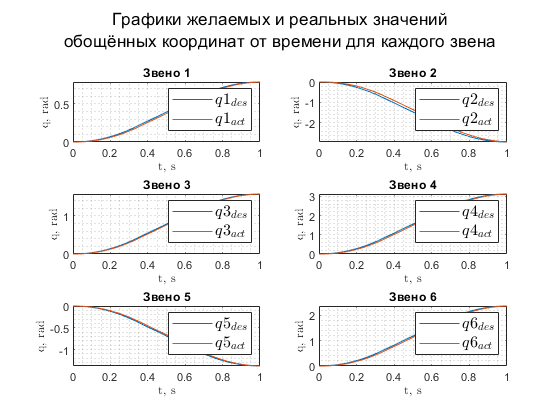

Amp_noise = [0 0 0 0 0 0];
Fr_noise = [0 0 0 0 0 0];
simout_ploop=sim('Lab3_Topolnitskii_ploop.slx');
% графики для изменения положений звеньев (обобщённые координаты)
figure;

subplot(3,2,1)
plot(simout_ploop.ploop.time', simout_ploop.ploop.signals.values(:,1))
hold on
plot(simout_ploop.ploop.time', simout_ploop.ploop.signals.values(:,2), 'LineStyle',"-")
title('Звено 1')
grid minor
legend('$q1_{des}$', '$q1_{act}$', 'fontsize',12,'interpreter','latex');
xlabel('t, s','Interpreter',"latex")
ylabel('q, rad','Interpreter',"latex")

subplot(3,2,2)
plot(simout_ploop.ploop.time', simout_ploop.ploop.signals.values(:,4))
hold on
plot(simout_ploop.ploop.time', simout_ploop.ploop.signals.values(:,5), 'LineStyle',"-")
title('Звено 2')
grid minor
legend('$q2_{des}$', '$q2_{act}$', 'fontsize',12,'interpreter','latex');
xlabel('t, s','Interpreter',"latex")
ylabel('q, rad','Interpreter',"latex")

subplot(3,2,3)
plot(simout_ploop.ploop.time', simout_ploop.ploop.signals.values(:,7))
hold on
plot(simout_ploop.ploop.time', simout_ploop.ploop.signals.values(:,8), 'LineStyle',"-")
title('Звено 3')
grid minor
legend('$q3_{des}$', '$q3_{act}$', 'fontsize',12,'interpreter','latex');
xlabel('t, s','Interpreter',"latex")
ylabel('q, rad','Interpreter',"latex")

subplot(3,2,4)
plot(simout_ploop.ploop.time', simout_ploop.ploop.signals.values(:,10))
hold on
plot(simout_ploop.ploop.time', simout_ploop.ploop.signals.values(:,11), 'LineStyle',"-")
title('Звено 4')
grid minor
legend('$q4_{des}$', '$q4_{act}$', 'fontsize',12,'interpreter','latex');
xlabel('t, s','Interpreter',"latex")
ylabel('q, rad','Interpreter',"latex")

subplot(3,2,5)
plot(simout_ploop.ploop.time', simout_ploop.ploop.signals.values(:,13))
hold on
plot(simout_ploop.ploop.time', simout_ploop.ploop.signals.values(:,14), 'LineStyle',"-")
title('Звено 5')
grid minor
legend('$q5_{des}$', '$q5_{act}$', 'fontsize',12,'interpreter','latex');
xlabel('t, s','Interpreter',"latex")
ylabel('q, rad','Interpreter',"latex")

subplot(3,2,6)
plot(simout_ploop.ploop.time', simout_ploop.ploop.signals.values(:,16))
hold on
grid minor
plot(simout_ploop.ploop.time', simout_ploop.ploop.signals.values(:,17), 'LineStyle',"-")
title('Звено 6')
legend('$q6_{des}$', '$q6_{act}$', 'fontsize',12,'interpreter','latex');
xlabel('t, s','Interpreter',"latex")
ylabel('q, rad','Interpreter',"latex")

sgtitle({'Графики желаемых и реальных значений';...
    'обощённых координат от времени для каждого звена'})

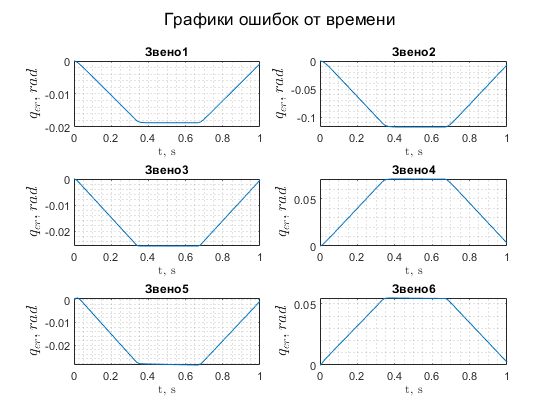

% графики для ошибки
figure()
k = 0;
for i = 3 : 3 : 18
    k = k + 1;
    subplot(3,2,k)
    plot(simout_ploop.ploop.time', simout_ploop.ploop.signals.values(:,i))
    grid minor
    xlabel('t, s','Interpreter',"latex")
    ylabel('${q_{er}, rad}$','Interpreter',"latex",'FontSize',12)
    title(['Звено',num2str(k)])
end
sgtitle({'Графики ошибок от времени'})

**Пунтк 9 и 10. Исследовать влияние шумов и массы на энд-эффекторе**

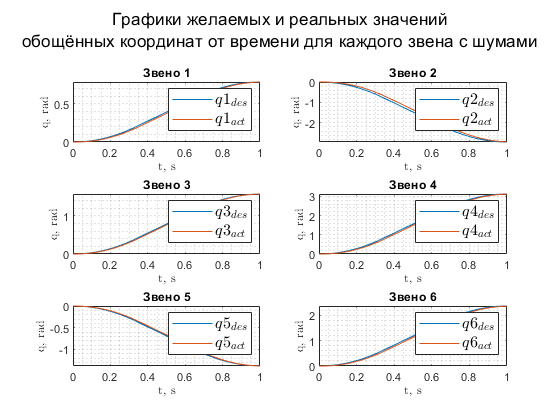

Amp_noise = [10 8 6 4 2 2]; % амплитуда шума
Fr_noise = [0.5 0.5 0.5 0.5 0.5 0.5]; % частота шума
simout_ploop = sim("Lab3_Topolnitskii_ploop.slx");
% графики по обобщённым координатам с учётом шума
figure;

subplot(3,2,1)
plot(simout_ploop.ploop.time', simout_ploop.ploop.signals.values(:,1))
hold on
plot(simout_ploop.ploop.time', simout_ploop.ploop.signals.values(:,2), 'LineStyle',"-")
title('Звено 1')
grid minor
legend('$q1_{des}$', '$q1_{act}$', 'fontsize',12,'interpreter','latex');
xlabel('t, s','Interpreter',"latex")
ylabel('q, rad','Interpreter',"latex")

subplot(3,2,2)
plot(simout_ploop.ploop.time', simout_ploop.ploop.signals.values(:,4))
hold on
plot(simout_ploop.ploop.time', simout_ploop.ploop.signals.values(:,5), 'LineStyle',"-")
title('Звено 2')
grid minor
legend('$q2_{des}$', '$q2_{act}$', 'fontsize',12,'interpreter','latex');
xlabel('t, s','Interpreter',"latex")
ylabel('q, rad','Interpreter',"latex")

subplot(3,2,3)
plot(simout_ploop.ploop.time', simout_ploop.ploop.signals.values(:,7))
hold on
plot(simout_ploop.ploop.time', simout_ploop.ploop.signals.values(:,8), 'LineStyle',"-")
title('Звено 3')
grid minor
legend('$q3_{des}$', '$q3_{act}$', 'fontsize',12,'interpreter','latex');
xlabel('t, s','Interpreter',"latex")
ylabel('q, rad','Interpreter',"latex")

subplot(3,2,4)
plot(simout_ploop.ploop.time', simout_ploop.ploop.signals.values(:,10))
hold on
plot(simout_ploop.ploop.time', simout_ploop.ploop.signals.values(:,11), 'LineStyle',"-")
title('Звено 4')
grid minor
legend('$q4_{des}$', '$q4_{act}$', 'fontsize',12,'interpreter','latex');
xlabel('t, s','Interpreter',"latex")
ylabel('q, rad','Interpreter',"latex")

subplot(3,2,5)
plot(simout_ploop.ploop.time', simout_ploop.ploop.signals.values(:,13))
hold on
plot(simout_ploop.ploop.time', simout_ploop.ploop.signals.values(:,14), 'LineStyle',"-")
title('Звено 5')
grid minor
legend('$q5_{des}$', '$q5_{act}$', 'fontsize',12,'interpreter','latex');
xlabel('t, s','Interpreter',"latex")
ylabel('q, rad','Interpreter',"latex")

subplot(3,2,6)
plot(simout_ploop.ploop.time', simout_ploop.ploop.signals.values(:,16))
hold on
grid minor
plot(simout_ploop.ploop.time', simout_ploop.ploop.signals.values(:,17), 'LineStyle',"-")
title('Звено 6')
legend('$q6_{des}$', '$q6_{act}$', 'fontsize',12,'interpreter','latex');
xlabel('t, s','Interpreter',"latex")
ylabel('q, rad','Interpreter',"latex")

sgtitle({'Графики желаемых и реальных значений';...
    'обощённых координат от времени для каждого звена с шумами'})

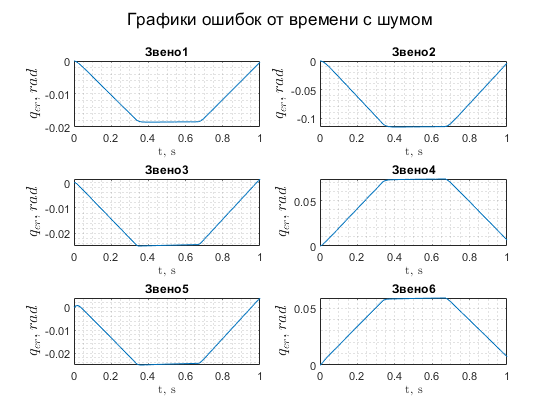

% графики для ошибки в случае добавления шумов
figure()
k = 0;
for i = 3 : 3 : 18
    k = k + 1;
    subplot(3,2,k)
    plot(simout_ploop.ploop.time', simout_ploop.ploop.signals.values(:,i))
    grid minor
    xlabel('t, s','Interpreter',"latex")
    ylabel('${q_{er}, rad}$','Interpreter',"latex",'FontSize',12)
    title(['Звено',num2str(k)])
end
sgtitle({'Графики ошибок от времени с шумом'})

Попробуем добавить полезную нагрузку на энд-эффектор. Это приведёт к изменению положения ц.м., потому необходимо пересчитать инерции.

clear simout_vloop simout_ploop
m = 4; % масса груза
irb140.payload(m,[0.05 0.09 0.1]); % задаём массу и изменение положения ц.м.

M = zeros(6, n); % зададим пустую матрицу
for i = 1 : size(q,1)
    M_full = irb140.inertia(q(i,:));  % для каждого звена вычисляем
    % матрицу инерции в зависимости от координат при движении по траектории
    M(1,i) = M_full(1,1);
    M(2,i) = M_full(2,2);
    M(3,i) = M_full(3,3);
    M(4,i) = M_full(4,4);
    M(5,i) = M_full(5,5);
    M(6,i) = M_full(6,6);
end
% вычислим среднее значение по траектории
M_mean = zeros(1, 6);
for i = 1 : 6
    M_mean(i) = mean(M(i,:));
end
% найдём отношение максимального к минимальному моментов инерции на
% траектории
ratio = zeros(1, 6);
for i = 1 : 6
    ratio(i) = max(M(i,:)) / min(M(i,:));
end
ratio

ratio =     8.0133    1.1805    1.1952    1.6811    1.1677    1.0000


for i = 1 : 6
    J(i) = irb140.links(1, i).Jm + M_mean(i) / irb140.links(1, i).G^2;
end

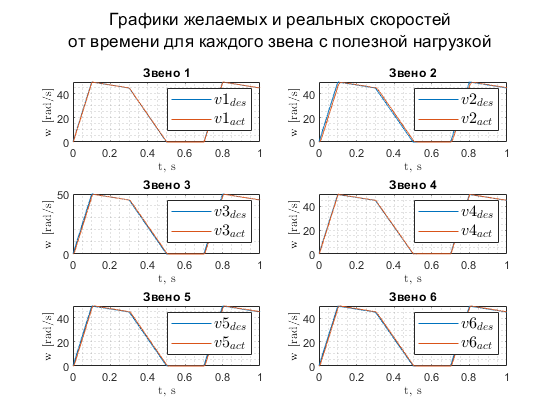

simout_vloop = sim("Lab3_Topolnitskii_velocity.slx");
% графики по скорости для каждого звена
figure;

subplot(3,2,1)
plot(simout_vloop.vloop.time', simout_vloop.vloop.signals.values(:,1))
hold on
plot(simout_vloop.vloop.time', simout_vloop.vloop.signals.values(:,2), 'LineStyle',"-")
title('Звено 1')
grid minor
legend('$v1_{des}$', '$v1_{act}$', 'fontsize',12,'interpreter','latex');
xlabel('t, s','Interpreter',"latex")
ylabel('w [rad/s]','Interpreter',"latex")

subplot(3,2,2)
plot(simout_vloop.vloop.time', simout_vloop.vloop.signals.values(:,6))
hold on
plot(simout_vloop.vloop.time', simout_vloop.vloop.signals.values(:,7), 'LineStyle',"-")
title('Звено 2')
grid minor
legend('$v2_{des}$', '$v2_{act}$', 'fontsize',12,'interpreter','latex');
xlabel('t, s','Interpreter',"latex")
ylabel('w [rad/s]','Interpreter',"latex")

subplot(3,2,3)
plot(simout_vloop.vloop.time', simout_vloop.vloop.signals.values(:,11))
hold on
plot(simout_vloop.vloop.time', simout_vloop.vloop.signals.values(:,12), 'LineStyle',"-")
title('Звено 3')
grid minor
legend('$v3_{des}$', '$v3_{act}$', 'fontsize',12,'interpreter','latex');
xlabel('t, s','Interpreter',"latex")
ylabel('w [rad/s]','Interpreter',"latex")

subplot(3,2,4)
plot(simout_vloop.vloop.time', simout_vloop.vloop.signals.values(:,16))
hold on
plot(simout_vloop.vloop.time', simout_vloop.vloop.signals.values(:,17), 'LineStyle',"-")
title('Звено 4')
grid minor
legend('$v4_{des}$', '$v4_{act}$', 'fontsize',12,'interpreter','latex');
xlabel('t, s','Interpreter',"latex")
ylabel('w [rad/s]','Interpreter',"latex")

subplot(3,2,5)
plot(simout_vloop.vloop.time', simout_vloop.vloop.signals.values(:,21))
hold on
plot(simout_vloop.vloop.time', simout_vloop.vloop.signals.values(:,22), 'LineStyle',"-")
title('Звено 5')
grid minor
legend('$v5_{des}$', '$v5_{act}$', 'fontsize',12,'interpreter','latex');
xlabel('t, s','Interpreter',"latex")
ylabel('w [rad/s]','Interpreter',"latex")

subplot(3,2,6)
plot(simout_vloop.vloop.time', simout_vloop.vloop.signals.values(:,26))
hold on
grid minor
plot(simout_vloop.vloop.time', simout_vloop.vloop.signals.values(:,27), 'LineStyle',"-")
title('Звено 6')
legend('$v6_{des}$', '$v6_{act}$', 'fontsize',12,'interpreter','latex');
xlabel('t, s','Interpreter',"latex")
ylabel('w [rad/s]','Interpreter',"latex")

sgtitle({'Графики желаемых и реальных скоростей';...
    'от времени для каждого звена с полезной нагрузкой'})

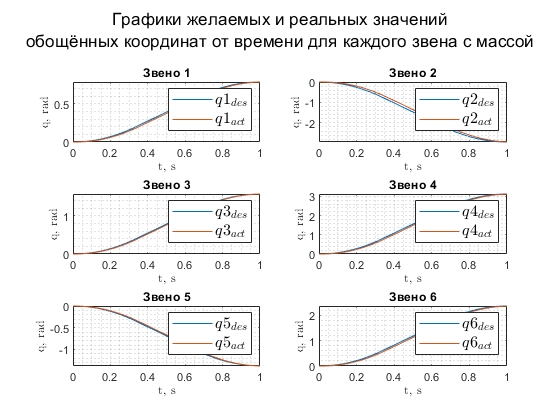


simout_ploop = sim("Lab3_Topolnitskii_ploop.slx");
% графики по обобщённым координатам с массы на энд-эффекторе
figure;

subplot(3,2,1)
plot(simout_ploop.ploop.time', simout_ploop.ploop.signals.values(:,1))
hold on
plot(simout_ploop.ploop.time', simout_ploop.ploop.signals.values(:,2), 'LineStyle',"-")
title('Звено 1')
grid minor
legend('$q1_{des}$', '$q1_{act}$', 'fontsize',12,'interpreter','latex');
xlabel('t, s','Interpreter',"latex")
ylabel('q, rad','Interpreter',"latex")

subplot(3,2,2)
plot(simout_ploop.ploop.time', simout_ploop.ploop.signals.values(:,4))
hold on
plot(simout_ploop.ploop.time', simout_ploop.ploop.signals.values(:,5), 'LineStyle',"-")
title('Звено 2')
grid minor
legend('$q2_{des}$', '$q2_{act}$', 'fontsize',12,'interpreter','latex');
xlabel('t, s','Interpreter',"latex")
ylabel('q, rad','Interpreter',"latex")

subplot(3,2,3)
plot(simout_ploop.ploop.time', simout_ploop.ploop.signals.values(:,7))
hold on
plot(simout_ploop.ploop.time', simout_ploop.ploop.signals.values(:,8), 'LineStyle',"-")
title('Звено 3')
grid minor
legend('$q3_{des}$', '$q3_{act}$', 'fontsize',12,'interpreter','latex');
xlabel('t, s','Interpreter',"latex")
ylabel('q, rad','Interpreter',"latex")

subplot(3,2,4)
plot(simout_ploop.ploop.time', simout_ploop.ploop.signals.values(:,10))
hold on
plot(simout_ploop.ploop.time', simout_ploop.ploop.signals.values(:,11), 'LineStyle',"-")
title('Звено 4')
grid minor
legend('$q4_{des}$', '$q4_{act}$', 'fontsize',12,'interpreter','latex');
xlabel('t, s','Interpreter',"latex")
ylabel('q, rad','Interpreter',"latex")

subplot(3,2,5)
plot(simout_ploop.ploop.time', simout_ploop.ploop.signals.values(:,13))
hold on
plot(simout_ploop.ploop.time', simout_ploop.ploop.signals.values(:,14), 'LineStyle',"-")
title('Звено 5')
grid minor
legend('$q5_{des}$', '$q5_{act}$', 'fontsize',12,'interpreter','latex');
xlabel('t, s','Interpreter',"latex")
ylabel('q, rad','Interpreter',"latex")

subplot(3,2,6)
plot(simout_ploop.ploop.time', simout_ploop.ploop.signals.values(:,16))
hold on
grid minor
plot(simout_ploop.ploop.time', simout_ploop.ploop.signals.values(:,17), 'LineStyle',"-")
title('Звено 6')
legend('$q6_{des}$', '$q6_{act}$', 'fontsize',12,'interpreter','latex');
xlabel('t, s','Interpreter',"latex")
ylabel('q, rad','Interpreter',"latex")

sgtitle({'Графики желаемых и реальных значений';...
    'обощённых координат от времени для каждого звена с массой'})

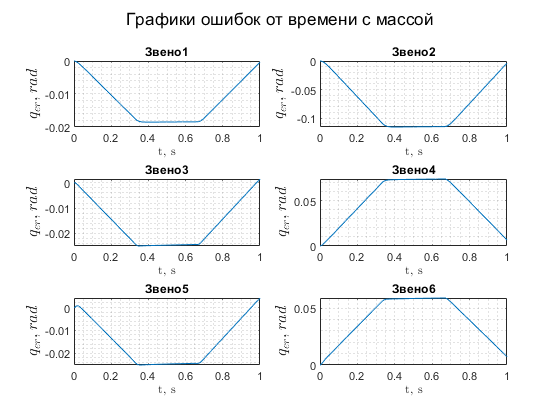

% графики для ошибки в случае добавления массы
figure()
k = 0;
for i = 3 : 3 : 18
    k = k + 1;
    subplot(3,2,k)
    plot(simout_ploop.ploop.time', simout_ploop.ploop.signals.values(:,i))
    grid minor
    xlabel('t, s','Interpreter',"latex")
    ylabel('${q_{er}, rad}$','Interpreter',"latex",'FontSize',12)
    title(['Звено',num2str(k)])
end
sgtitle({'Графики ошибок от времени с массой'})

**Вывод:**

В ходе выполнения лабораторной работы были взяты параметры двигателей для каждого из звеньев и настроены пропорциональный и интегральный коэффициенты регуляторов для каждого звена. Была рассчитана инерция каждого звена с учётом предыдущего звена. В файле с контуром управления по положению была также проведена настройка регулятора для каждого звена. Для случаев, когда добавляются шумы или полезная нагрузка на энд-эффектор, ошибка всё также остаётся незначительной, а в конце траектории практически нулевая. 